# Algoritmos Numéricos por Computadora

# Primer Examen Parcial

# Primavera 2023

Sube tu archivo resultado (con las respuestas visibles) a Canvas $\to$ Examen Parcial 1 antes de las 11:25 horas.

Cada pregunta vale 5 puntos.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

Revisa que en el archivo que entregues se vean claramente todas tus respuestas.

Recuerda salvar frecuentemente tu archivo.

Puede ser conveniente limpiar periódicamente el espacio de trabajo (clear en command window).

En el caso extremo de gráficas que aparecen mal, puedes salir y volver a entrar a la sesión.

1. Demuestra que:

a) Dados $x_1 ,x_{2,} x_3$, la fórmula para calcular la siguiente aproximación $x_r \;$en el método de interpolación cuadrática inversa utilizado para encontrar una raíz de la función$f\left(x\right)$ es:

% xr = (x1*f2*f3)/((f1-f2)*(f1-f3)) + ...
%      (x2*f1*f3)/((f2-f1)*(f2-f3)) + ... 
%      (x3*f1*f2)/((f3-f1)*(f3-f2));


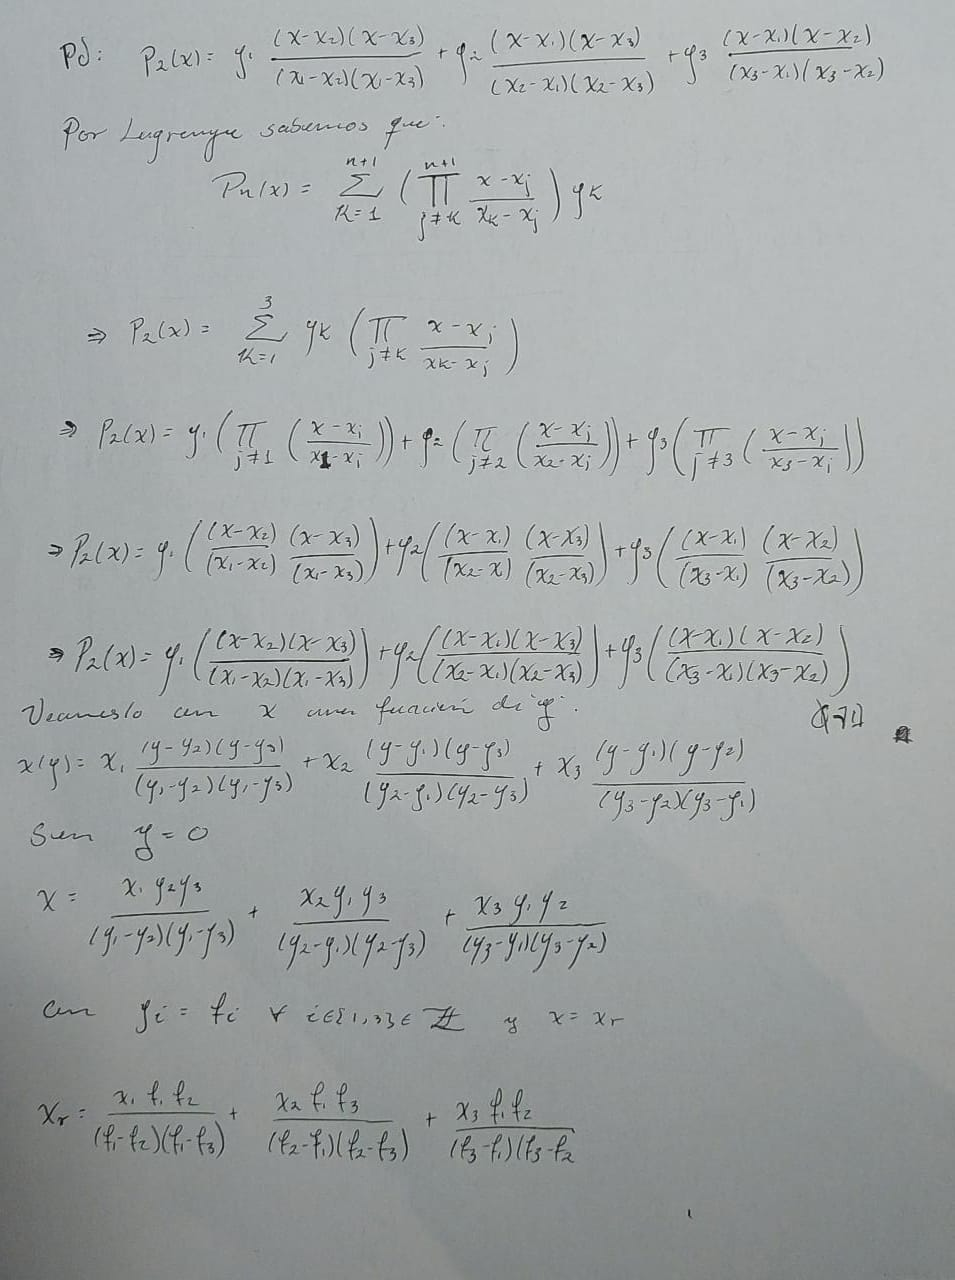

b) Dados $r,s,t$, la fórmula para calcular la siguiente aproximación $x_c \;$en el método de interpolación parabólica sucesiva utilizado para encontrar un punto crítico de la función$f\left(x\right)$ es:

% xc = ((r+s) - (fs-fr)*(t-r)*(t-s)/((s-r)*(ft-fs)-(fs-fr)*(t-s)))/2;


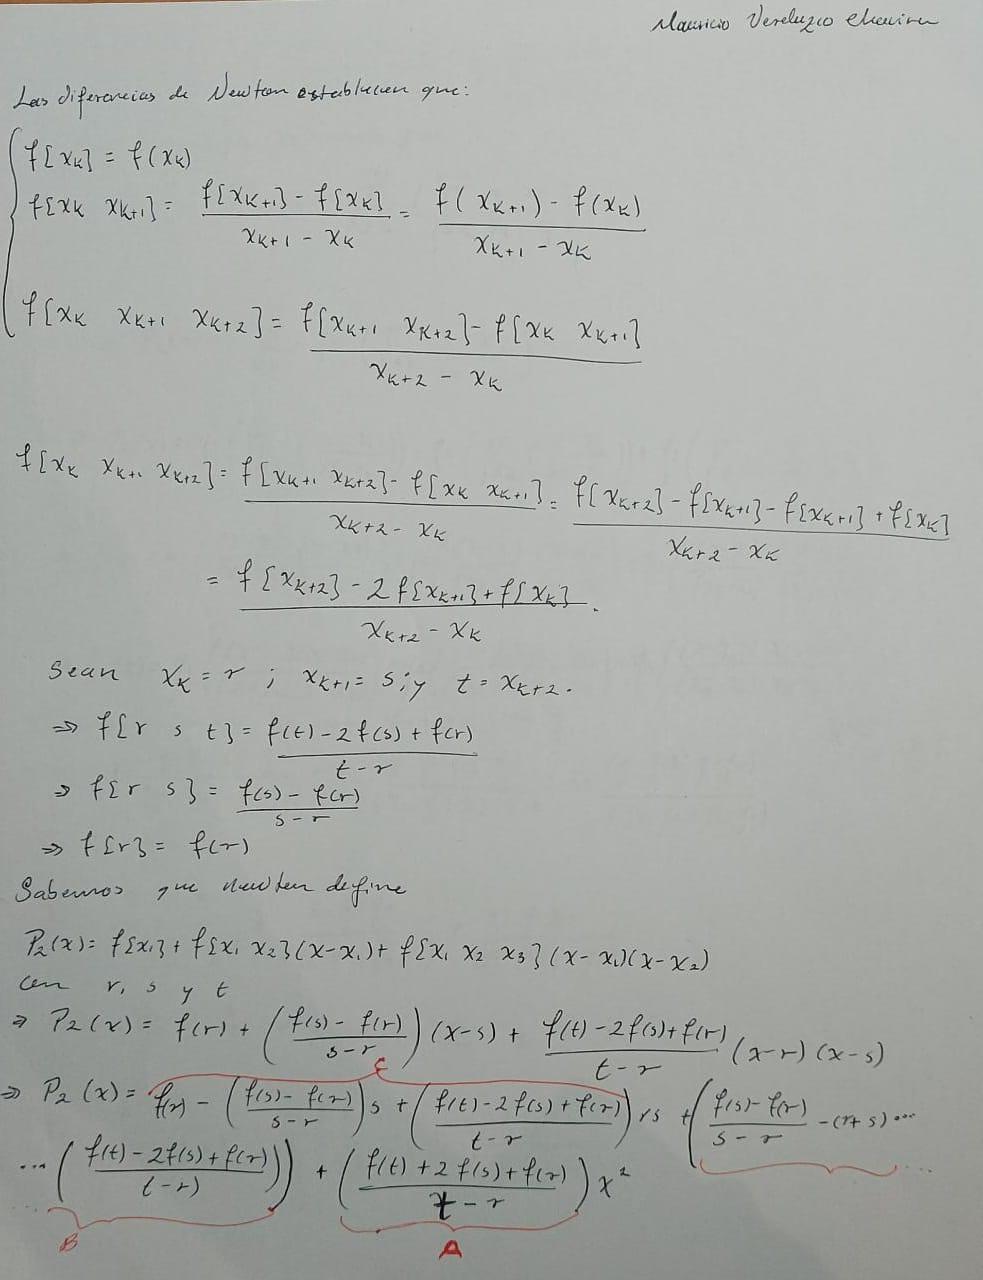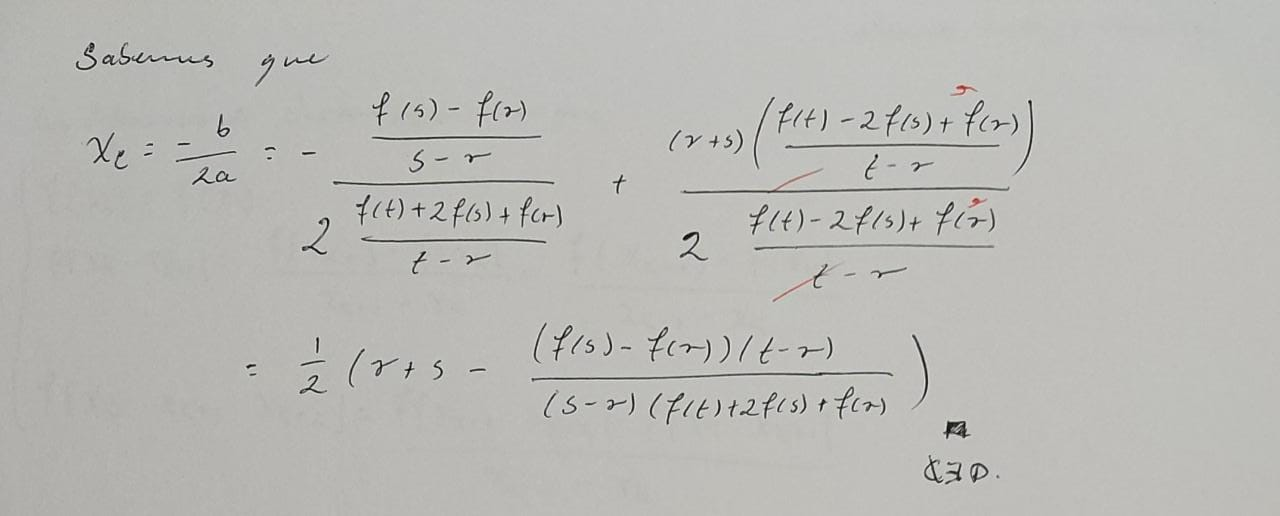

2. Representación de números reales en el estándard IEEE 754.


$$x=\pm \left(1\ldotp f\right)2^e$$


a) ¿Cúantos números de punto flotante (precisión doble, normalizados) pueden representarse de manera exacta en MATLAB? Justifica tu respuesta en términos de $\pm$, $e$ y $f$.

% f puede tomar del bit 13 al 64, esto son 52 bits. Y la exponencial puede
% tomar 2^11-2 bits (le restamos 2 por los caracteres especiales como NaN,
% Inf, etc.). Y el signo puede tomar 2^1 valores. 
fs = 2^52

fs = 4.5036e+15

exps = 2^11-2

exps = 2046

sign = 2

sign = 2

numTot = fs*exps*sign

numTot = 1.8429e+19


%Aproximadamente 1.8e+19 números posibles. 


b) ¿Qué fracción de estos números se encuentra en el intervalo $2\le x<4$? (Tip: ¿qué exponente $e$  tienen estos números? ¿Qué signo tienen?)

%Para alcanzar esos valores necesitmos 2^1 y pero ya que el intervalo excluye el 4, 
% no necesitamos  2^2. Es decir solo existen los números posibles con las 
% combincaciones que hay respecto a un valor de la exponencial para
% todo el intervalo posible para el exponente. 
% En otras palabras, podemos
% cambiar a todas las combinaciones posibles de los bits para la 'f' y el 's', pero
% los 11-2 bits de la exponencial que permiten 1024 números solo
% utilizaremos uno para expresar este intervalo. 

%Representado en fracción tendíamos 1/(2*(2^11 -2))


c) ¿Qué fracción de estos números se encuentra en el intervalo $0<x<1$? (Tip: ¿qué exponentes tienen estos números?¿Qué signo tienen?)

% Este caso es similar al anterior, para calcular los números entre 1 y
% cero sin incluir el 1 ni el cero tenemos el signo positivo y TODOS los
% exponentes negativos que son 1023.


d) ¿Qué limita el numéro finito de bits en $f$ ?

%  f tiene que existir entre 0 < f < 1. Para calcular utilizamos
%  (f<2^(52))/52. Esto significa que f no puede ser más grande que 2^52
%  pues al dividirlo entre dicha potencia de dos, tendríamos un número
%  mayor

% Todo lo anterior La precisión con la que puedo describir un número por
% ejemplo los dígitos con los que aproximo Pi.


e) ¿Qué limita el numéro finito de bits en $e$ ?

% El rango de números que puedo tener, la diferencia entre el mínimo 
% y el máximo. Si elijo un número “muy grande” para MatLAB tomando 
% en cuenta esos 11 bits limitados por su exponente, lo tomará 
% como un “infinito”. 

3. Calcula, utilizando tres métodos diferentes, el radio $r$ de una esfera cuyo volumen ($\frac{4}{3}\pi r^3$) es $\pi$${\textrm{cm}}^3$.

a) Plantea la función $f\left(r\right)=0$.

f=@(R) 4/3*pi*R.^3 - pi;

b) Grafica la función

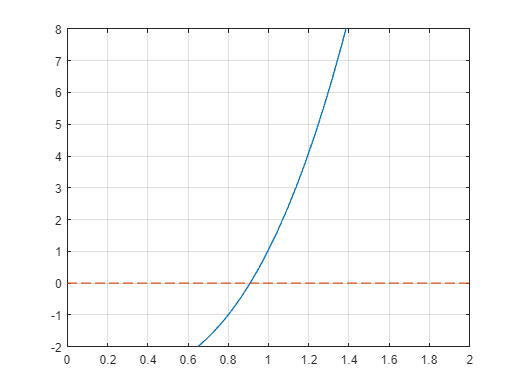

fplot(f)
%Ya que no puede haber radios negativos, ploteamos r>0
axis([0 2 -2 8])
hold on
y = 0;
fplot(y,'--')
hold off
grid on

c) Usa tres métodos diferentes para encontrar la respuesta:

[x2(1),i2(1)] = R1_Biseccion(f,1, -1); %Convergencia Lineal
[x2(2),i2(2)] = R2_Interpolacion(f,1, -1); %Convergencia Lineal
[x2(3),i2(3)] = R3_Secante(f,1, -1); %Diferencias Invertido
[x2(4),i2(4)] = R4_rfNewton(f,0); %Convergencia Cuadríatica 
[x2(5),i2(5)] = R5_InterpolacionCuadraticaInversa(f, 1,0, -1);%Convergenia cuadrática inversa


d) Explica las diferencias en la rapidez de convergencia (medida en número de iteraciones). ¿Por qué un método converge más rápido que otro?

x2

x2 =     0.9086    0.9086    0.9086       Inf    0.7500


i2

i2 =     53    27    10     1     2


%Podemos ver que no todos los métodos encontraron una respuesta, de hecho,
%pareciera que la respuesta correcta es "ronda el 0.9", sin embargo, tenemos que preguntarnos qué método
%lo alcanzó. Esto se deberá a la presisión del intervalo que existe en esta
%función.  

%Supiniendo que el resultado obtenido es correcto las primeras tres
%funciones tomaron 53, 27 y 10 iteraciones (respectivamente). La cuarta
%función no alcanzó el resultado. La quinta función llegó a un resultado
%distinto, más cercano a cero en tan solo dos iteraciones.

%La conclusión es que la raíz está en 0.9086 y el mejor método fue el de
%Secante porque llegó al resultado en 10 iteraciones. Esto es menos de la
%mitad de iteraciones del siguiente método. 



4. Un saltador de bungee es proyectado hacia arriba con una velocidad inicial $v_0$.  En este problema una velocidad hacia arriba se considera positiva. La altura $z$  del saltador, sobre la superficie de la Tierra, está dada por la siguiente ecuación (que es la solución de una ecuación diferencial):


$$z\left(t\right)=z_0 +\frac{m}{c}\left(v_0 +\frac{m\;g}{c}\right)\left(1+e^{-\frac{c}{m}t} \right)-\frac{m\;g}{c}t$$


donde: $g=9\ldotp 81\frac{m}{s^2 }$,  $m=80\;\textrm{kg}$, $c=15\;\frac{\textrm{kg}}{c}$  (coeficiente lineal de arrastre), $z_0 =100\;m$ (altura inicial) y $v_0 =55\frac{m}{s}$.

g = 9.81;
m = 80;
c = 15;
v0 = 55;
z0= 100;
z = @(t) z0+(m/c)*(v0+(m*g)/c)*(1-exp((-c/m)*t))-(m*g/c)*t;

a) Grafica la función $z\left(t\right)$ en el intervalo [0,10].

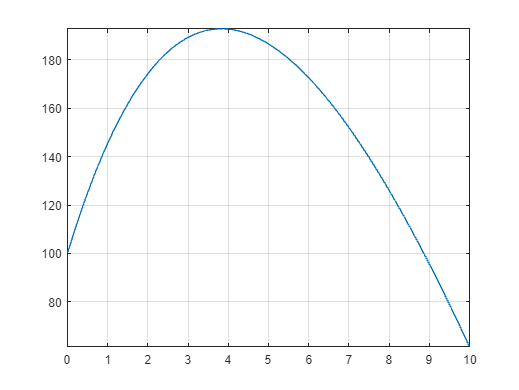

fplot(z, [0, 10])
grid on

b) Determina el tiempo exacto en el que se alcanza el pico de elevación usando dos métodos de optimización diferentes.

%Aproximando con proporción Aurea
g = @(x) -z(x)

g = function_handle with value:
    @(x)-z(x)


x1 = O1_proporcionAurea(g,3, 4)

x1 = 3.8317


%Aproximando con optimización de Newton
O2_newtonRaphsonMinimo(z,4)

ans = 3.8317


%Aproximando con IPS
O3_IPS(z,4.5, 4, 5.5)

ans = 3.8317


%El tiempo es de 3.83 segundos

c) Determina la altura máxima alcanzada.

ans = z(x1)

ans = 192.8609

% 192.8609

5. Muestra que la función $g\left(x\right)=\sqrt{1+x}$ tiene exactamente un punto fijo y calcúlalo.

Un punto fijo de una función es un elemento que la función mapea en sí mismo $x=g\left(x\right)$. 

a) Grafica la función $g\left(x\right)$ y la función identidad $\textrm{id}\left(x\right)=x$ y muestra que se cruzan en un solo punto.

g = @(x) sqrt(1+x)

g = function_handle with value:
    @(x)sqrt(1+x)


fplot(g, [1 2])
hold on
id = @(x) x

id = function_handle with value:
    @(x)x


fplot(id, [1 2])

b) Encuentra el punto en el que se cruzan las dos gráficas (el punto fijo).

h = @(x) id(x)-g(x);

[x1(1),i1(1)] = R1_Biseccion(h,1.4, 1.8);
[x1(2),i1(2)] = R2_Interpolacion(h,1.4, 1.8);
[x1(3),i1(3)] = R3_Secante(h,1.4, 1.8);
[x1(4),i1(4)] = R4_rfNewton(h,1.6);
[x1(5),i1(5)] = R5_InterpolacionCuadraticaInversa(h, 1.4, 1.6, 1.8);

(x1)

x1 =     1.6180    1.6180    1.6180    1.6180    1.6180


(i1)

i1 =     49     8     5     4     2


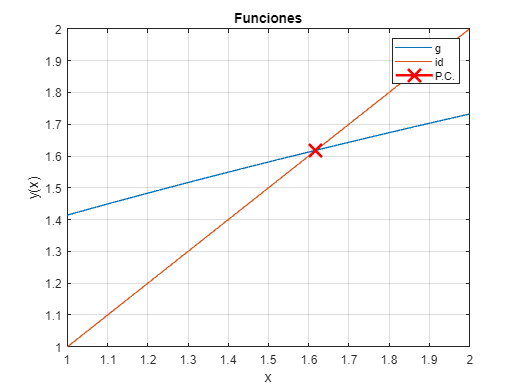


fplot(id,[x1(1),x1(1)+0.000001], 'x-r', 'LineWidth',2, 'MarkerSize',15)
legend('g', 'id', 'P.C.')
xlabel("x")
ylabel("y(x)")
title("Funciones")
grid on
hold off

6. Muestra, mediante un programa eficiente y bien escrito, que si se denota el i-ésimo número de Fibonacci como $F_i$, y al siguiente número de Fibonacci como $F_{i+1}$, se tiene que $\underset{i\to \infty }{\lim \;} \frac{f_{i+1} }{f_i }=\varphi$. 


$$f_1 =1$$



$$f_2 =1$$



$$f_i =f_{i-1} +f_i \;\;\;\;\;\;\;\;\;\;\;\;i\ge 3$$


El programa debe inicialmente calcular y almacenar los primeros $n$ números de Fibonacci en un vector y luego calcular los cocientes, graficarlos y deplegar el último valor.

a) Calcula y almacena los primeros 100 números de Fibonacci

n = 100

n = 100

f = zeros(1,n)

f =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


f = fibonacci(1:n)

f = 1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


disp(f)

   1.0e+20 *

  Columns 1 through 20

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 21 through 40

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 41 through 60

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 61 through 80

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002

  Columns 81 through 100

    0.0004    0.0006    0.0010    0.0016    0.0026   

b) Calcula los cocientes de manera eficiente

coc = f(2:n)./f(1:end-1)

coc =     1.0000    2.0000    1.5000    1.6667    1.6000    1.6250    1.6154    1.6190    1.6176    1.6182    1.6180    1.6181    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180    1.6180


c) Grafica los cocientes y despliega el último valor

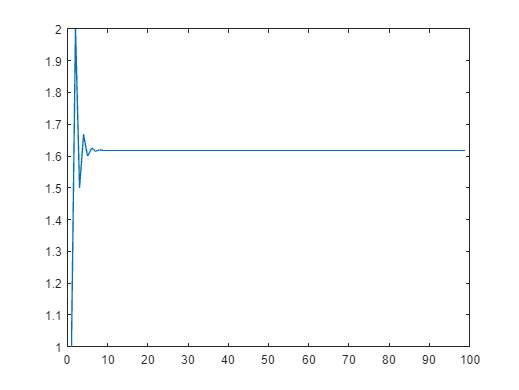

plot(coc)

phi = (coc(end))

phi = 1.6180

Escribe aquí los códigos de las funciones utilizadas:

% function [x,i] = O1_proporcionAurea(f,xl,xu)
% max = 55;
%     tol = sqrt(eps);
%     i = 0;
%     g = (1+sqrt(5))/2 - 1;
%     d = g *(xu-xl);
%     x1 = xl + d;
%     x2 = xu - d;
%     cond =  true;
%     fx1 = f(x1);
%     fx2 = f(x2);
% 
%     while cond
%         d = d*g;
%         
%         if fx1<fx2
%             xl = x2;
%             x2 = x1;
%             fx2 = fx1;
%             x1 = xl + d;
%             fx1 = f(x1);
%         else
%             xu = x1;
%             x1 = x2;
%             fx1 = fx2;
%             x2 = xu - d;
%             fx2 = f(x2);
%         end
%         i = i+1;
%         cond = i < max && abs(xu-xl)/(abs(xu)+abs(xl)) > tol;
%     end
%     x = (xu+xl)/2;
% end


% function [x,i, min] = O2_newtonRaphsonMinimo(f,x)
%     %Parámetros iniciales
%     max = 52;
%     tol = sqrt(eps);
%     i = 0;
%     cond =  true;
% 
%     %Declaramos las funciones anónimas
%     f = f;
%     fs = sym(f);
%     dfs = diff(fs);
%     dfs2 = diff(dfs);
%     df = matlabFunction(dfs);
%     df2 = matlabFunction(dfs2);
% 
%     
%     if nargin(df)<1
%         error('Function has not second reivate')
%     end
%     
%     if nargin(df2) < 1
%         df2 = @(x) df2();
%     end
% 
%     while cond
%         xp = x;
%         x = xp-df(xp)/df2(xp);
%         cond = abs((x-xp)/x) > tol && i < max;
%         i = i+1;
%     end
%     min = df2(x) > 0;
%     
% end


% function [x, i] = O3_IPS(f, r, s, t)
%     
%     tol = sqrt(eps);
%     imax = 53;
%     cond = true;
%     i = 0;
%     fr = f(r);
%     fs = f(s);
%     ft = f(t);
%     
%     while cond
% 
%         x = (r+s)/2 - ((fs-fr)*(t-r)*(t-s))/(2*((s-r)*(ft-fs)-(fs-fr)*(t-s)));
%         fx = f(x);
%         r = s;
%         fr = fs;
%         s = t;
%         fs = ft;
%         t = x;
%         ft = fx;
%         cond = abs(x-s)>(abs(s)+abs(x))*tol && i <imax;
%         fx = f(x);
%         i = i+1;
%     
%     end
%     if(i >= imax)
%         error('IPS:IterationLimitExceeded', 'Iteration limit exceeded')
%     end
% end


% function [xr,i]= R1_Biseccion(f,xl,xu)
%      if sign(f(xl))*sign(f(xu)) >= 0
%         error('f(xl)f(xu) < 0 no se satisface')
%      end
%     
%      MAX = 55;
%      tolerancia = eps;
%      xr = (xl+xu)/2;
%      fx = f(xr);
%      i = 0;
%      
%      while abs((xu-xl)/xu) > tolerancia && fx~=0 && i < MAX 
%          if sign(fx) ~= sign(f(xl))
%              xu = xr;
%          else
%              xl = xr;
%          end
%          xr=(xl+xu)/2;
%          fx=f(xr);
%          i=i+1;
%      end
% end


% function [x,i] = R2_Interpolacion(f,xl,xu)
% %Parámentros iniciales
% max = 52;
% tol = eps;
% cond =  true;
% i = 0;
% xr = 0;
% xv = 0;
% f = f;
% 
% while cond
%     %Calculamos primer xr
%     xr = xl-(f(xl)*(xu-xl))/(f(xu)-f(xl));
%     %Asignamos xr a xu o xl de acuerdo al signo
%     if f(xr)<0
%         xl=xr;
%     else
%         xu=xr;
%     end
%     %Calculamos error y reverificamos condición 
%     er = abs((xr-xv)/xr);
%     cond = er > tol && i < max;
%     %Aumentamos contador, guardamos en previo
%     xv = xr;
%     i = i+1;
% end
% 
% %Resultados
% x = xr;
% i = i;
% end


% function [x,i] = R3_Secante(f,xl,xu)
%         %Parámetros iniciales
%     max = 53;
%     tol = eps;
%     cond =  true;
%     i = 0;
%     
%     x = xu;
%     fx = f(x);
%     xp = xl;
%     fxp = f(xp);
% 
%     while cond
%         sn = (fx-fxp)/(x-xp);
%         xp = x;
%         fxp = fx;
%         x = xp - fxp/sn;
%         fx = f(x);
%         i = i+1;
%         cond = i<max && abs((x-xp)/x)>tol;
%     end
% end


% function [x,i] = R4_rfNewton(fun,x)
% itmax = 52;
% TolX = eps;    
% 
% xp=x;
%     i=0;
%     condicion=true;
%     while(condicion)
%         df=df1c(fun,xp);
%         dx=-(fun(xp)/df);
%         x=xp+dx;
%         xp=x;
%         i=i+1;
%         condicion=(abs(dx)>TolX*abs(x)) && i<itmax;
%     end
%     if(i>=itmax)
%         %Nos pasamos de iteraciones
%         error('rfNewtonR:IterationLimitExceeded','Iteration limit exceeded')
%     else
%         x=xp;
%     end
% end

% function [x, i] = R5_InterpolacionCuadraticaInversa(f, x1, x2, x3)
%     itmax = 52;
%     rTol = eps;  
%     i=0;
%     condicion=true;
%     f1=f(x1);
%     f2=f(x2);
%     while(condicion)
%         f3=f(x3);
%         x=((x1*f2*f3)/((f1-f2)*(f1-f3))+(x2*f1*f3)/((f2-f1)*(f2-f3))+(x3*f1*f2)/((f3-f1)*(f3-f2)));
%         i=i+1;
%         f1=f2;
%         f2=f3;
%         x1=x2;
%         x2=x3;
%         x3=x;
%         condicion=(abs(x-x2)<rTol*abs(x)) && i<itmax;
%         i=i+1;
%     end
%     if(i>=itmax)
%         %Nos pasamos de iteraciones
%         error('secante:IterationLimitExceeded','Iteration limit exceeded');
%     end
% end
%   
